# Session 2 - training a classification model

This notebook gives you a starting point for the second session, where we try to automatically classify if a patient has a disease from the FastSurfer outputs.

After uploading, we start with a brief data exploration part.

## Load the data from the .csv file

[file_name, file_path] = uigetfile(".csv", "Point to the 'fsfaststats' .csv file here.");
data = readtable(fullfile(file_path, file_name));

rng(1); % For reproducibility

## Prepare data - shuffle rows and choose features

% Shuffle data so that there's no bias based on ordering of rows.
perm_index = randperm(height(data));
perm_data = data(perm_index, :);

% Make the response variable categorical for easier reading of output.
perm_data.Disease = categorical(perm_data.Disease,[0, 1, 2],{'Healthy' 'ASD' 'Epilepsy'});

% Select features - save 'disease' for the response. Subject is not really
% useful as it is unique. Also remove it.
feature_columns = setdiff(perm_data.Properties.VariableNames, {'Disease', 'Subject'});

## Create predictors and response variables.

X = perm_data(:, feature_columns);
y = perm_data.Disease;

n_samples = height(X);

% Choose 80% of the samples for training, and rest for testing.
n_train = floor(0.8 * n_samples);

Xtrain = X(1:n_train, :);
ytrain = y(1:n_train);

Xtest = X(n_train+1:end, :);
ytest = y(n_train+1:end);

## Create a bagged tree classifier choosing the number of trees in the ensemble

Change the parameters for the classifier to check how it impacts test accuracy (see next)

n_trees = 5;

baggedTree = TreeBagger(n_trees, Xtrain, ytrain, 'OOBPrediction', 'On', 'Method','classification')

baggedTree =   TreeBagger
Ensemble with 5 bagged decision trees:
                    Training X:            [1308x96]
                    Training Y:             [1308x1]
                        Method:       classification
                 NumPredictors:                   96
         NumPredictorsToSample:                   10
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:           'ASD'      'Epilepsy'       'Healthy'

  Properties, Methods


%% Optionally, display the first decision tree
%view(baggedTree.Trees{1},'Mode','graph');

## Evaluate model on test set

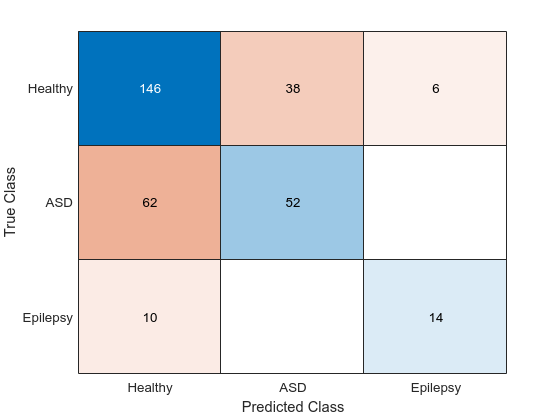

y_pred = predict(baggedTree, Xtest);
% Make response categorical - 
y_pred = categorical(y_pred);

% Then plot confusion matrix:
confusionchart(ytest, y_pred)